# Performance evaluation and comparison

close all; clear all; clc;
addpath('data\');
addpath('output\');
addpath('source\');

data = load('drugvir.mat');
X = data.drugvir;

topN = [1,5,10,15,20,25,30];

[~, maxrecallPerVirus_tSVD] = recall( 'tSVD', topN, 'testing');
[~, maxrecallPerVirus_NMF] = recall( 'NMF', topN, 'testing');
[~, maxrecallPerVirus_cNMF] = recall( 'cNMF', topN, 'testing');
[~, maxrecallPerVirus_random] = recall( 'random', topN, 'testing');

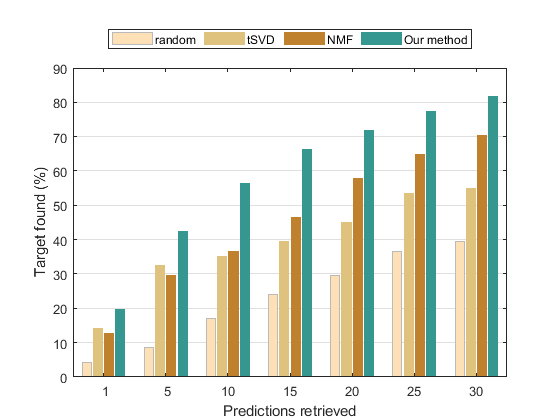

colors = [254,224,182;...
         223,194,125;...
         191,129,45;...
         53,151,143]./255;

figure;
b = bar(100*[maxrecallPerVirus_random; maxrecallPerVirus_tSVD; maxrecallPerVirus_NMF; maxrecallPerVirus_cNMF]');
for i = 1:4
  b(i).FaceColor = colors(i,:);
  if i == 1
      b(i).EdgeColor = [186,186,186]./255;
  else
      b(i).EdgeColor = colors(i,:);
  end
end
set(gca, 'YGrid', 'on', 'XGrid', 'off')
ylabel('Target found (%)');
set(gca, 'XTickLabel', num2str(topN'));
%title('recall per virus');
xlabel('Predictions retrieved')
legend({ 'random', 'tSVD', 'NMF', 'Our method'},"Orientation","horizontal", 'Location',"northoutside");